# **RT-QIBC analysis**

**POI(:,3): CRL4Cdt2 activation time**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
%     'Cdt1 -> GMNN',2,2,1:4,[0 0 0]; %1   
        'Cdt1 -> GMNN',2:5,2:4,1:4,[0 0 0]; %1      
        'GMNN -> Cdt1',2:5,6:8,1:4,[0 0 0]; %1      

        'CCNA',2:4,10:11,1:4,[0 0 0]; %1 
    };

load([dataDir filesep 'C225_data.mat'],'S');
% S = loadData(conditions, dataDir);
framesPerHr = 60/10;
frameDrugAdded = 0;
frameEdU = 0;
timeStart = 3.5;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

times = arrayfun(@(x)(numFrames - x.POI)/framesPerHr,S,'UniformOutput',false);
[S.POI_time] = times{:};

**Set gates**

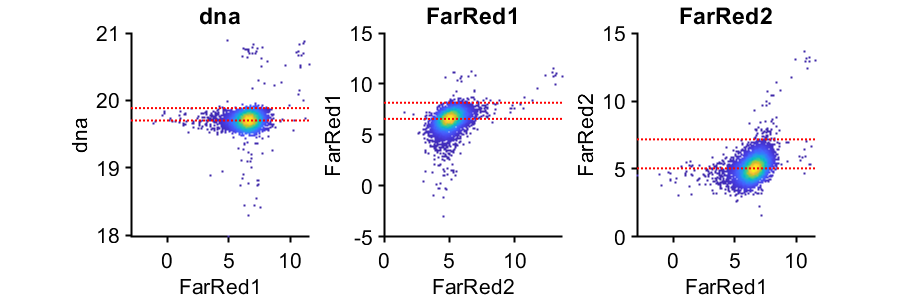


%% Set gates time after mitosis
cond=2;
gate = struct();
gates = {'dna','FarRed1','FarRed2'};
plotting = {'FarRed1','FarRed2','FarRed1'};
prctiles = {[50 99],[50 99],[50 99]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,1) <= 2 & S(cond).POI_time(:,1) > 1 & S(cond).dna < 2^21.5;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_G1']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_G1'])))
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
    if strcmp(gates{i},'FarRed2')
        g1cellsedu = ydata;
    end
    if strcmp(gates{i},'FarRed1')
        g1cellsgem = ydata;
    end
end

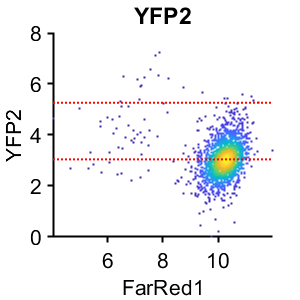



%% set S phase gates
cond=2;
gates = {'YFP2'};
plotting = {'FarRed1'};
prctiles = {[50 99]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,3) <= 2 &  S(cond).POI_time(:,3) > 1 ;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_S']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_S'])))
    
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
end

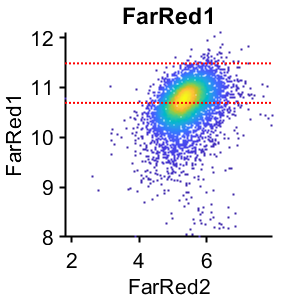


%% set G2 phase gates
cond=2;
gates = {'FarRed1'};
plotting = {'FarRed2'};
prctiles = {[50 99]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,5) > 0 & S(cond).FarRed2 < 2*gate.FarRed2_G1(2) & S(cond).POI_time(:,3) < 10 &...
        S(cond).FarRed1 > 2^8;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_G2']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_G2'])))
    
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
    if strcmp(gates{i},'FarRed1')
        g2cellsgem = ydata;
    end

end

**Time since CRL IF levels for export**

cond=2;
poiAligned=3;
offset=0;


rng(1)
gateVals = {{}};
rangeVals = {{[]}};

xrange = [0 10];

ind= ~isnan(S(cond).POI_time(:,poiAligned(1))) & ...
    gate_vals(S(cond), gateVals{1}, rangeVals{1});

xdata = S(cond).POI_time(ind,poiAligned);
ydata = [];
ydata(:, 1) = (S(cond).FarRed1(ind) - gate.FarRed1_G1(1))/(gate.FarRed1_G2(1)- gate.FarRed1_G1(1));
ydata(:, 2) = log2(S(cond).FarRed2(ind)) ;

edges = unique(xdata);
[binData, edges] = bin_xy(xdata, ydata, {'mean','median'},...
    'Edges',edges);
midpoints = edges;
midpoints = midpoints(1:end-1);


f1 = figure('Units', 'Inches', 'Position', [0, 0, 6, 4]);
hold on
subG1 = randsample(log2(g1cellsedu),300);
subs_cells = randsample(size(ydata,1),6000);
subs = false(size(ydata,1),1);
subs(subs_cells) = true;
% subs = subs & ydata(:,1) < 2 & ydata(:,1) > -.1;
fakexg1 = rand(size(subG1)) - 1.7;
%dscatter(xdata,ydata2);
scatter(xdata(subs),ydata(subs,2),20,'k','filled','MarkerFaceAlpha',.1)
scatter(fakexg1,subG1 ,20,'k','filled','MarkerFaceAlpha',.1)
plot(midpoints,binData(2).median,'r','LineWidth',2);
ylim([3 15]);
xlim([-3 10]);
ylabel('log2(EdU) (AU)');xlabel({'Time since S phase entry (hrs)'});
%title(conditions{conds(i),1});
h=hline(log2(gate.FarRed2_G1(2)),'k');
hold off
print_pdf([pwd() '\Figs\EdU_timesinceS.pdf'])


f2 = figure('Units', 'Inches', 'Position', [0, 0, 6, 4]);
hold on
%dscatter(xdata,ydata3);
subG1 = (randsample(g1cellsgem,200) - gate.FarRed1_G1(1)) /(gate.FarRed1_G2(1)- gate.FarRed1_G1(1));
% subG2 = randsample(g2cellsgem,400)/gate.YFP2_G2(1);
fakexg1 = rand(size(subG1)) - 1.7;
% fakexg2 = rand(size(subG2)) + 9;
scatter(xdata(subs),ydata(subs,1) ,20,'k','filled','MarkerFaceAlpha',.1)
scatter(fakexg1,subG1 ,20,'k','filled','MarkerFaceAlpha',.1)
% scatter(fakexg2,subG2 ,20,'k','filled','MarkerFaceAlpha',.1)
plot(midpoints,binData(1).median,'r','LineWidth',2);
ylim([-.2 2.5]);
xlim([-3 10]);
ylabel('Geminin (Norm. to G2 levels)');xlabel({'Time since S phase entry (hrs)'});
%title(conditions{conds(i),1});
% h=hline(gate.YFP2_G1(2),'k--');
hold off
print_pdf([pwd() '\Figs\GMNN_timesinceS.pdf'])


**stat test gem comparison **

Gate for early mitosis, first .3 hrs, high/low geminin

rng(2)
yval = 'FarRed1';

f1 = figure;
test = {};
ally = [];
group = [];

%%% G1 levels
condition = 2;
ydata = g1cellsgem;
inds = randsample(length(ydata),400);
ydata = ydata(inds);

% ydata(ydata<0) = [];
test{1} = ydata;
ally = [ally; ydata];
group = [group; repmat(1,size(ydata))];

%%% early S phase cells
condition =  2;
ydata = S(condition).(yval);

inds = S(condition).POI_time(:,3) <= 3*10/60 & S(condition).dna < 2^20.25 ;
ydata = ydata(inds);

% ydata(ydata<0) = [];
test{2} = ydata;
ally = [ally; ydata];
group = [group; repmat(2,size(ydata))];


%%% G2 levels
condition = 2;
ydata = g2cellsgem;

inds = randsample(length(ydata),5000);
ydata = ydata(inds);

test{3} = ydata;
ally = [ally; ydata];
group = [group; repmat(3,size(ydata))];



% ally = ally - median(ally(group ==1));
ally = (ally - median(ally(group == 1)))/(median(ally(group == 3))- median(ally(group == 1)));
test = cellfun(@(x) (x - median(test{1}))/(median(test{3})- median(test{1})),test,'UniformOutput',false);
cellfun(@median,test)

ans =          0    0.2307    1.0000


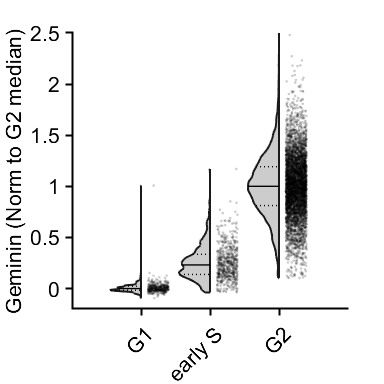



figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
    'xNames',{'G1','early S','G2'});
set(h{1},'EdgeColor',[.1 .1 .1],'LineWidth',1.5)
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(group+jit, (ally), 4,'k','filled','MarkerFaceAlpha',.2);
ylabel('Geminin (Norm to G2 median)')
ylim([-.2 2.5])
xtickangle(45)
pbaspect([1 1 1])
print_pdf([pwd() '\Figs\gmnn_compare_scatter.pdf'])